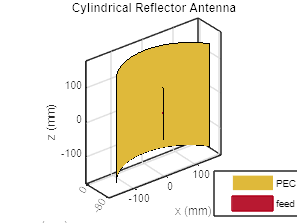









%% Cylindrical Reflector Antenna Design and Visualization
GL = 0.3;                  % Ground plane length (m)
GW = 0.3;                  % Ground plane width (m)
D  = 0.075;                % Depth (m)

% Create cylindrical reflector object
cref = reflectorCylindrical( ...
    GroundPlaneLength = GL, ...
    GroundPlaneWidth = GW, ...
    Depth = D);

% Set tilt parameters
cref.Tilt = 90;
cref.Exciter.TiltAxis = [1 0 0];
cref.Exciter.Tilt = 90;

% Visualize antenna
figure;
show(cref);
title("Cylindrical Reflector Antenna");

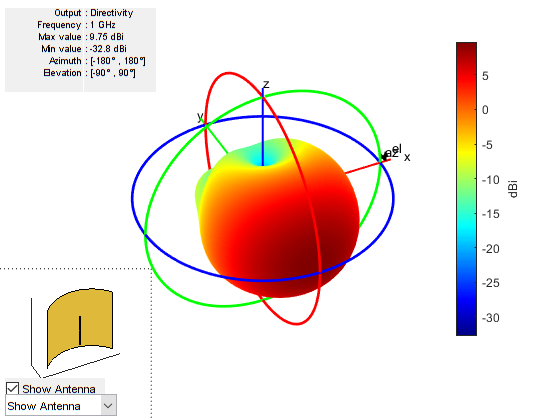






%% Cylindrical Reflector Radiation Pattern at 1 GHz
figure;
pattern(cref, 1e9);
view(-26, 39);
title("Radiation Pattern of Cylindrical Reflector at 1 GHz");

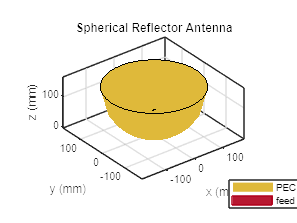

%% Spherical Reflector Antenna Design
R = 0.15;     % Radius (m)
D = 0.15;     % Depth (m)

% Create spherical reflector
sref = reflectorSpherical( ...
    Radius = R, ...
    Depth = D);

% Visualize spherical reflector
figure;
show(sref);
title("Spherical Reflector Antenna");

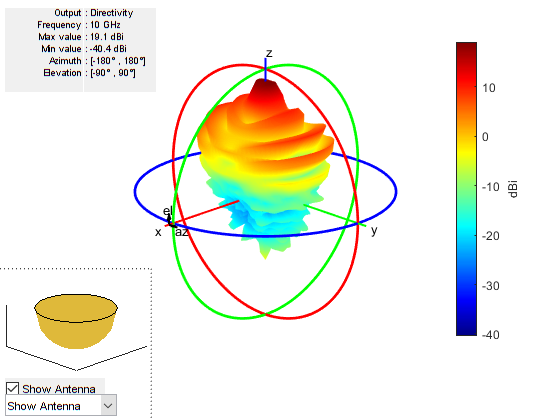

%% Spherical Reflector Radiation Pattern at 10 GHz
figure;
pattern(sref, 10e9);
title("Radiation Pattern of Spherical Reflector at 10 GHz");

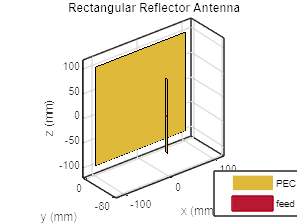

%% Rectangular Reflector Antenna Design
antR = reflector;
antR.Tilt = 90;
antR.Exciter.TiltAxis = [1 0 0];
antR.Exciter.Tilt = 90;

figure;
show(antR);
title("Rectangular Reflector Antenna");

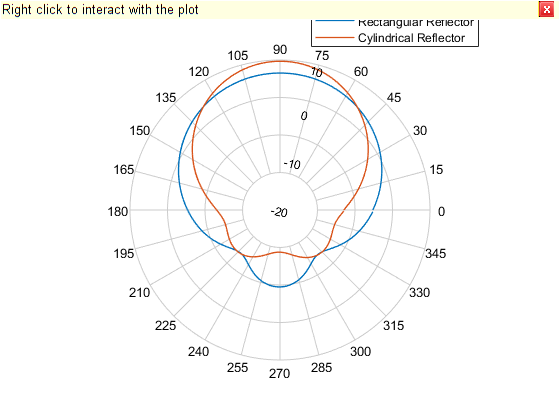

%% Azimuth Radiation Patterns Comparison
pa1 = patternAzimuth(antR, 1e9, 0, "Azimuth", 0:-1:-360);
pa2 = patternAzimuth(cref, 1e9, 0, "Azimuth", 0:-1:-360);

figure;
polarpattern(pa1);
hold on;
polarpattern(pa2);
hold off;

legend("Rectangular Reflector", "Cylindrical Reflector");
title("Azimuth Radiation Pattern Comparison");

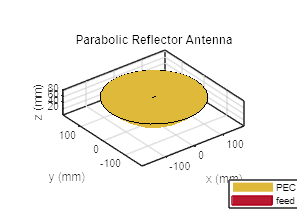

%% Parabolic Reflector Antenna Design
pref = reflectorParabolic;

figure;
show(pref);
title("Parabolic Reflector Antenna");

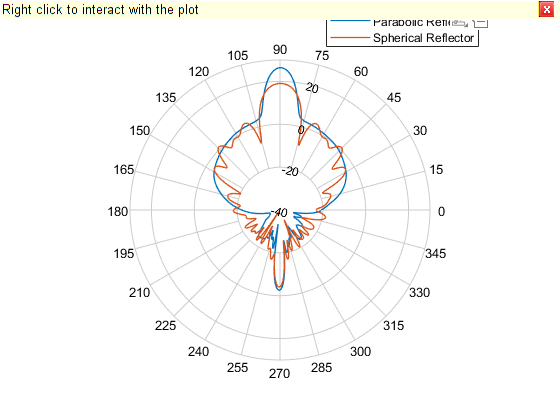


%% Elevation Pattern Comparison at 10 GHz
pe1 = patternElevation(pref, 10e9, 0, Elevation = 0:360);
pe2 = patternElevation(sref, 10e9, 0, Elevation = 0:360);

figure;
polarpattern(pe1);
hold on;
polarpattern(pe2);
hold off;

legend("Parabolic Reflector", "Spherical Reflector");
title("Elevation Pattern Comparison at 10 GHz");